# Asesoria

### Metodos Numericos

#### 2022-2S : 10/10/2022

clear
syms P(x) [1 3]
syms k [1 2] real
syms A B C D E
syms a x real

P1(x) = A * exp(-i * k1 * x) + B * exp(i * k1 * x)

$$P1(x) = A\,{\mathrm{e}}^{-k_{1}\,x\,\mathrm{i}}+B\,{\mathrm{e}}^{k_{1}\,x\,\mathrm{i}}$$

P2(x) = C * exp(- k2 * x) + D * exp(k2 * x)

$$P2(x) = C\,{\mathrm{e}}^{-k_{2}\,x}+\text{D}\,{\mathrm{e}}^{k_{2}\,x}$$

P3(x) = E * exp(i * k1 * x) 

$$P3(x) = \text{E}\,{\mathrm{e}}^{k_{1}\,x\,\mathrm{i}}$$

dP1(x) = diff(P1(x), x)

$$dP1(x) = -A\,k_{1}\,{\mathrm{e}}^{-k_{1}\,x\,\mathrm{i}}\,\mathrm{i}+B\,k_{1}\,{\mathrm{e}}^{k_{1}\,x\,\mathrm{i}}\,\mathrm{i}$$

dP2(x) = diff(P2(x), x)

$$dP2(x) = \text{D}\,k_{2}\,{\mathrm{e}}^{k_{2}\,x}-C\,k_{2}\,{\mathrm{e}}^{-k_{2}\,x}$$

dP3(x) = diff(P3(x), x)

$$dP3(x) = \text{E}\,k_{1}\,{\mathrm{e}}^{k_{1}\,x\,\mathrm{i}}\,\mathrm{i}$$

Eq1 = P1(0) == P2(0);
Eq2 = P2(a) == P3(a);
Eq3 = dP1(0) == dP2(0);
Eq4 = dP2(a) == dP3(a);

sol = solve(Eq1, Eq2, Eq3, Eq4, {A, B, C, D}, 'ReturnConditions', true);
sol.conditions

$$ans = k_{1}\neq 0\wedge k_{2}\neq 0$$

A = simplify(sol.A)

$$A = -\frac{\text{E}\,{\mathrm{e}}^{a\,\left(-k_{2}+k_{1}\,\mathrm{i}\right)}\,\left({\mathrm{e}}^{2\,a\,k_{2}}-1\right)\,\left({k_{1}}^{2}+{k_{2}}^{2}\right)\,\mathrm{i}}{4\,k_{1}\,k_{2}}$$

B = simplify(sol.B)

$$B = \begin{array}{l} -\frac{\text{E}\,\left(-{k_{1}}^{2}\,\sigma_{1}+{k_{2}}^{2}\,\sigma_{1}+{k_{1}}^{2}\,\sigma_{2}-{k_{2}}^{2}\,\sigma_{2}+2\,k_{1}\,k_{2}\,\sigma_{1}\,\mathrm{i}+2\,k_{1}\,k_{2}\,\sigma_{2}\,\mathrm{i}\right)\,\mathrm{i}}{4\,k_{1}\,k_{2}}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{a\,\left(-k_{2}+k_{1}\,\mathrm{i}\right)}\\ \sigma_{2}={\mathrm{e}}^{a\,\left(k_{2}+k_{1}\,\mathrm{i}\right)} \end{array}$$

P1(x) = A * exp(-i * k1 * x) + B * exp(i * k1 * x);
conj(P1)

$$ans(x) = \begin{array}{l} -\frac{{\mathrm{e}}^{-k_{1}\,x\,\mathrm{i}}\,\bar{\text{E}}\,\left(-{k_{1}}^{2}\,\sigma_{2}+{k_{2}}^{2}\,\sigma_{2}+{k_{1}}^{2}\,\sigma_{1}-{k_{2}}^{2}\,\sigma_{1}+2\,k_{1}\,k_{2}\,\sigma_{2}\,\mathrm{i}+2\,k_{1}\,k_{2}\,\sigma_{1}\,\mathrm{i}\right)\,\mathrm{i}}{4\,k_{1}\,k_{2}}+\frac{{\mathrm{e}}^{k_{1}\,x\,\mathrm{i}}\,\sigma_{1}\,\bar{\text{E}}\,\left({\mathrm{e}}^{2\,a\,k_{2}}-1\right)\,\left({k_{1}}^{2}+{k_{2}}^{2}\right)\,\mathrm{i}}{4\,k_{1}\,k_{2}}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-a\,\left(k_{2}+k_{1}\,\mathrm{i}\right)}\\ \sigma_{2}={\mathrm{e}}^{-a\,\left(-k_{2}+k_{1}\,\mathrm{i}\right)} \end{array}$$

int(P1 * conj(P1), x, [-inf, 0])

$$ans = \begin{array}{l} -\left(\lim_{x\to -\infty }\frac{x\,\sigma_{3}\,{\left|\text{E}\right|}^{2}\,\left({k_{1}}^{4}\,{\mathrm{e}}^{4\,a\,k_{2}}-2\,{k_{2}}^{4}\,{\mathrm{e}}^{2\,a\,k_{2}}-2\,{k_{1}}^{4}\,{\mathrm{e}}^{2\,a\,k_{2}}+{k_{2}}^{4}\,{\mathrm{e}}^{4\,a\,k_{2}}+{k_{1}}^{4}+{k_{2}}^{4}+2\,{k_{1}}^{2}\,{k_{2}}^{2}+4\,{k_{1}}^{2}\,{k_{2}}^{2}\,{\mathrm{e}}^{2\,a\,k_{2}}+2\,{k_{1}}^{2}\,{k_{2}}^{2}\,{\mathrm{e}}^{4\,a\,k_{2}}\right)}{{k_{1}}^{2}\,{k_{2}}^{2}\,8}+\frac{{\mathrm{e}}^{-2\,x\,k_{1}\,\mathrm{i}-2\,a\,k_{2}}\,{\left|\text{E}\right|}^{2}\,\sigma_{2}\,\sigma_{1}\,\sigma_{7}}{\sigma_{4}}+\frac{{\mathrm{e}}^{2\,x\,k_{1}\,\mathrm{i}-2\,a\,k_{2}}\,{\left|\text{E}\right|}^{2}\,\sigma_{2}\,\sigma_{1}\,\sigma_{6}}{\sigma_{4}}\right)+\frac{\sigma_{3}\,{\left|\text{E}\right|}^{2}\,\sigma_{2}\,\sigma_{1}\,\sigma_{6}}{\sigma_{5}}+\frac{\sigma_{3}\,{\left|\text{E}\right|}^{2}\,\sigma_{2}\,\sigma_{1}\,\sigma_{7}}{\sigma_{5}}\\ \mathrm{where}\\ \sigma_{1}={k_{1}}^{2}+{k_{2}}^{2}\\ \sigma_{2}={\mathrm{e}}^{2\,a\,k_{2}}-1\\ \sigma_{3}={\mathrm{e}}^{-2\,a\,k_{2}}\\ \sigma_{4}={k_{1}}^{3}\,{k_{2}}^{2}\,32\\ \sigma_{5}=32\,{k_{1}}^{3}\,{k_{2}}^{2}\\ \sigma_{6}=2\,k_{1}\,k_{2}+\sigma_{10}-\sigma_{9}+\sigma_{8}+{k_{1}}^{2}\,\mathrm{i}-{k_{2}}^{2}\,\mathrm{i}\\ \sigma_{7}=2\,k_{1}\,k_{2}+\sigma_{10}+\sigma_{9}-\sigma_{8}-{k_{1}}^{2}\,\mathrm{i}+{k_{2}}^{2}\,\mathrm{i}\\ \sigma_{8}={k_{2}}^{2}\,{\mathrm{e}}^{2\,a\,k_{2}}\,\mathrm{i}\\ \sigma_{9}={k_{1}}^{2}\,{\mathrm{e}}^{2\,a\,k_{2}}\,\mathrm{i}\\ \sigma_{10}=2\,k_{1}\,k_{2}\,{\mathrm{e}}^{2\,a\,k_{2}} \end{array}$$

simplify(ans)

$$ans = \begin{array}{l} -\left(\lim_{x\to -\infty }\frac{x\,\sigma_{3}\,{\left|\text{E}\right|}^{2}\,\left({k_{1}}^{4}\,{\mathrm{e}}^{4\,a\,k_{2}}-2\,{k_{2}}^{4}\,{\mathrm{e}}^{2\,a\,k_{2}}-2\,{k_{1}}^{4}\,{\mathrm{e}}^{2\,a\,k_{2}}+{k_{2}}^{4}\,{\mathrm{e}}^{4\,a\,k_{2}}+{k_{1}}^{4}+{k_{2}}^{4}+2\,{k_{1}}^{2}\,{k_{2}}^{2}+4\,{k_{1}}^{2}\,{k_{2}}^{2}\,{\mathrm{e}}^{2\,a\,k_{2}}+2\,{k_{1}}^{2}\,{k_{2}}^{2}\,{\mathrm{e}}^{4\,a\,k_{2}}\right)}{{k_{1}}^{2}\,{k_{2}}^{2}\,8}+\frac{{\mathrm{e}}^{-2\,x\,k_{1}\,\mathrm{i}-2\,a\,k_{2}}\,{\left|\text{E}\right|}^{2}\,\sigma_{2}\,\sigma_{1}\,\sigma_{7}}{\sigma_{4}}+\frac{{\mathrm{e}}^{2\,x\,k_{1}\,\mathrm{i}-2\,a\,k_{2}}\,{\left|\text{E}\right|}^{2}\,\sigma_{2}\,\sigma_{1}\,\sigma_{6}}{\sigma_{4}}\right)+\frac{\sigma_{3}\,{\left|\text{E}\right|}^{2}\,\sigma_{2}\,\sigma_{1}\,\sigma_{6}}{\sigma_{5}}+\frac{\sigma_{3}\,{\left|\text{E}\right|}^{2}\,\sigma_{2}\,\sigma_{1}\,\sigma_{7}}{\sigma_{5}}\\ \mathrm{where}\\ \sigma_{1}={k_{1}}^{2}+{k_{2}}^{2}\\ \sigma_{2}={\mathrm{e}}^{2\,a\,k_{2}}-1\\ \sigma_{3}={\mathrm{e}}^{-2\,a\,k_{2}}\\ \sigma_{4}={k_{1}}^{3}\,{k_{2}}^{2}\,32\\ \sigma_{5}=32\,{k_{1}}^{3}\,{k_{2}}^{2}\\ \sigma_{6}=2\,k_{1}\,k_{2}+\sigma_{10}-\sigma_{9}+\sigma_{8}+{k_{1}}^{2}\,\mathrm{i}-{k_{2}}^{2}\,\mathrm{i}\\ \sigma_{7}=2\,k_{1}\,k_{2}+\sigma_{10}+\sigma_{9}-\sigma_{8}-{k_{1}}^{2}\,\mathrm{i}+{k_{2}}^{2}\,\mathrm{i}\\ \sigma_{8}={k_{2}}^{2}\,{\mathrm{e}}^{2\,a\,k_{2}}\,\mathrm{i}\\ \sigma_{9}={k_{1}}^{2}\,{\mathrm{e}}^{2\,a\,k_{2}}\,\mathrm{i}\\ \sigma_{10}=2\,k_{1}\,k_{2}\,{\mathrm{e}}^{2\,a\,k_{2}} \end{array}$$

clear
syms f(x, y)
syms x y real

f(x, y) = [sin(x) + exp(y), x*y^2 + 3 * cos(x) + 14]

$$f(x, y) = \left(\begin{array}{cc} {\mathrm{e}}^{y}+\sin\left(x\right) & x\,y^{2}+3\,\cos\left(x\right)+14 \end{array}\right)$$

J(x, y) = jacobian(f, [x, y])

$$J(x, y) = \left(\begin{array}{cc} \cos\left(x\right) & {\mathrm{e}}^{y}\\ y^{2}-3\,\sin\left(x\right) & 2\,x\,y \end{array}\right)$$

f = matlabFunction(f);
J = matlabFunction(J);
f = @(U) f(U(1), U(2));
J = @(U) J(U(1), U(2));

X0 = [4 1];
C = newdim(f, J, X0, 1e-6, 1e-8, 100)

C =    -6.4831   -1.6165


clear

t = 1:6;
V = [21308 38827 48150 66157 114042 149133];

[A, b] = lsline(log(t + 10), log(V));
A, C = exp(b)

A = 5.0663

C = 0.1165

V = @(t) C* (t + 10)^A;

V0 = V(7)

V0 = 1.9967e+05

Vreal = 169219;

errorR = abs(Vreal - V0) / Vreal

errorR = 0.1800

errorR * 100

ans = 17.9962

clear
syms a b c d alpha beta real
digits(4)
b = solve( 6 == (8 - 2) / (1 - b) )

$$b = 0$$

beta = vpa(solve(beta == (-4/15 - -2) / (11/2 - b)))

$$beta = 0.3152$$

alpha = vpa(solve(-2 == (alpha - 6) / (3 - b)))

$$alpha = 0.0$$

clear
syms x
digits(4)

f = @(x) exp(x) - sin(4 * x);
X = linspace(0, 4, 10);
Y = f(X);
C = lspoly(X, Y, 5)

C =     0.1057
   -0.5974
    1.6261
   -0.6788
    1.3518
    0.7774


vpa(poly2sym(C, x))

$$ans = 0.1057\,x^{5}-0.5974\,x^{4}+1.626\,x^{3}-0.6788\,x^{2}+1.352\,x+0.7774$$

P = @(x) polyval(C, x);

Error = P(X) - f(X);
sum((P(X) - f(X)).^2)

ans = 4.4079

norm(Error)^2

ans = 4.4079

clear

X = [0 .2857 .5714 .8571 1.1429 1.4286 1.7143 2];
Y = [1 2.0929 2.9604 3.8445 4.8534 6.0770 7.6141 9.5863];

[m1, b] = lsline(X, Y)

m1 = 4.0861

b = 0.6674

X = [ X .4 ];
Y = [ Y 5 ];

[m2, b] = lsline(X, Y)

m2 = 3.7023

b = 1.3255

alpha = @(m1, m2) 180/pi * atan((m2 - m1) / (1 + m1.*m2));

alpha(m1, m2)

ans = -1.3635

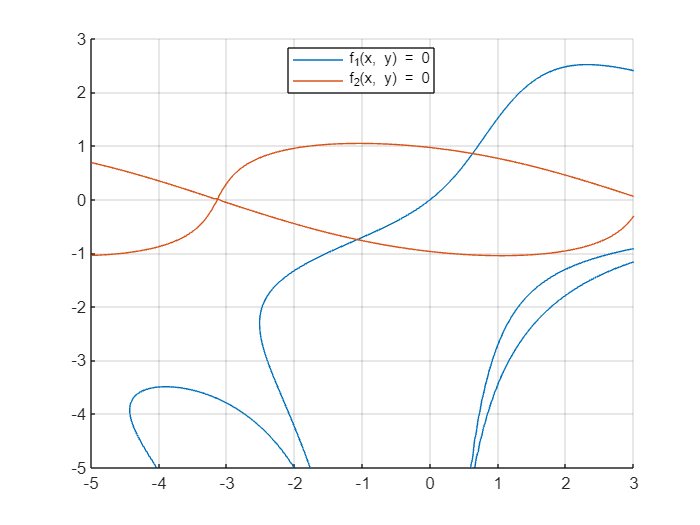

clear
syms f(x, y)
syms x y real

f1(x, y) = sin(x * y / 2) - exp(y - x) + 1; f2(x, y) = exp(y^2) - cos(x + y) - 2;

clf("reset")
hold on
fimplicit(f1 == 0, [-5, 3], 'DisplayName', 'f_1(x, y) = 0')
fimplicit(f2 == 0, [-5, 3], 'DisplayName', 'f_2(x, y) = 0')
grid on
legend('Location', 'best')

syms F(x,y)
F(x,y)=[sin(x*y/(2))-exp(y-x) + 1, exp(y^2)-cos(x+y)-2]

$$F(x, y) = \left(\begin{array}{cc} \sin\left(\frac{x\,y}{2}\right)-{\mathrm{e}}^{y-x}+1 & {\mathrm{e}}^{y^{2}}-\cos\left(x+y\right)-2 \end{array}\right)$$

JF = jacobian(F, [x, y]);
F=matlabFunction(F);
JF=matlabFunction(JF);
F = @(X) F(X(1), X(2)) % expresamos de forma de vector F

F = function_handle with value:
    @(X)F(X(1),X(2))


JF = @(X) JF(X(1), X(2)) % xpresamos de forma de vector Jacobiano

JF = function_handle with value:
    @(X)JF(X(1),X(2))


P0=[0.5 0.5]; delta=1e-6;  epsilon=1e-8;  max1=100;
[P, iter, err] = newdim (F, JF, P0, delta, epsilon, max1)

P =     0.6236    0.8582


iter = 5

err = 3.1611e-07